% Define units
meter = 1;
millimeter = 10^(-3) * meter;
nanometer = 10^(-9) * meter;

%README: Introducing alot of new functions, half of them are plotting related
%The most important feature of 2d, is 1: using the 2d Fourier transform, 2: dealing with 2d sample coordinates
%Sample coordinates for 2d need an array (N,N, 2) shape. The last 2 is to store not just an x coordinate,
%but also a y coordinate
%generate_2d_coordinates, propagate_fresnel_2d, small_angle_mirror_phase,
%plot_2d_phase, plot_2d_intensity, normalize

%%%TASK: 
%%%Complete the centroid (centroid.m) function by correctly multiplying the respective coordinate on the normalized
%%%intensity distribution before the integral is computed (in this case approximately by sum).
%%%HINT:
%%%function super_gaussian_cos.m has a good example of accessing only the x or only the y coordinate from 2d sample coordinates.

%%%QUESTION: 
%%%Which of the above two equations (in the pdf) gives the normalization condition for the transverse intensity? 
%%%How would the above calculated centroid change if the total intensity was not normalized to unity?


% Coordinates and amplitude pattern to test the centroid
coordinates_centroid_example = generate_2d_coordinates(512, 2 * millimeter);

% Notice shift is nonzero
complicated_amplitude = super_gaussian_cos(coordinates_centroid_example, 0.5 * millimeter, [0.1 * millimeter, 0.05 * millimeter]);

% Calculate the centroid
[cx, cy] = centroid(coordinates_centroid_example, complicated_amplitude);

% Plot 2D intensity with centroid information in the title
plot_2d_intensity(coordinates_centroid_example, complicated_amplitude, ['Centroid(mm): ', num2str(round(cx / millimeter, 4)), ', ', num2str(round(cy / millimeter, 4))]);
['Centroid(mm): ', num2str(round(cx / millimeter, 4)), ', ', num2str(round(cy / millimeter, 4))]

ans = 'Centroid(mm): 0.1, 0.05'

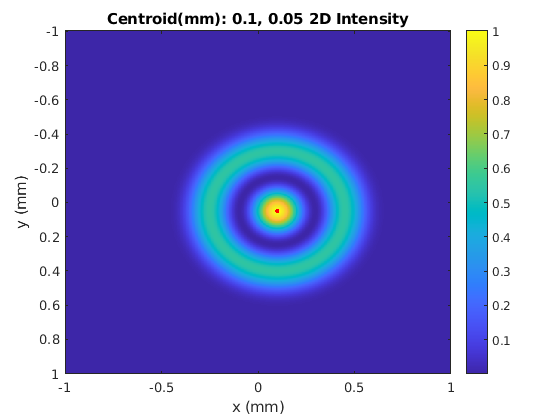

% Plot the centroid
hold on; % Keep the current plot
plot(cx / millimeter, cy / millimeter, '.r'); % Plot centroid as red circle
hold off; % Release the plot hold

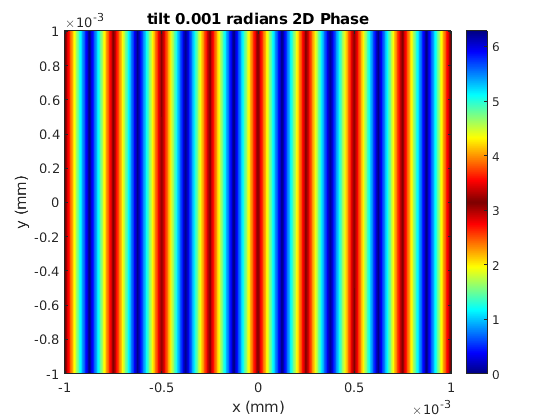

%%%TASK: generate a mirror tilt phase about the transverse Y axis for a 0.001 rad tilt, to apply on the given beam. 
%%%HINT: use the provided mirror tilt function
%%%The tilt will be applied to the above beam used in the centroid example


%%%QUESTION: Using the centroids of the tilted propagations and initial condition, make a small
%%%angle calculation of the angle of reflection. Does it match the expected
%%%angle of reflection?

lambda = 500 * nanometer; % Wavelength

% Generate the tilt phase for a 0.001 rad tilt about the transverse Y axis
tilt_phase = small_angle_mirror_phase(%%%Fill in here);

% Apply the tilt phase to the complicated amplitude
tilted_wavefront_amplitude = (%%%Fill in here) .* complicated_amplitude;

% Plot the tilt phase
plot_2d_phase(coordinates_centroid_example, tilt_phase, 'tilt 0.001 radians');

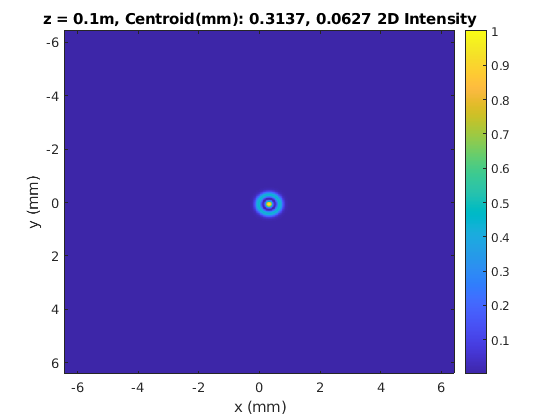

figure; % Create a new figure for the next plot

% Propagate the example amplitude to 0.1 meters with the tilt phase applied
[propagated_coordinates, propagated_amplitude] = propagate_fresnel_2d(coordinates_centroid_example, tilted_wavefront_amplitude, lambda, 0.1 * meter);

% Calculate centroid
[cx, cy] = centroid(propagated_coordinates, propagated_amplitude);
plot_2d_intensity(propagated_coordinates, propagated_amplitude, ['z = 0.1m, Centroid(mm): ', num2str(round(cx / millimeter, 4)), ', ', num2str(round(cy / millimeter, 4))]);

cx

cx = 3.1370e-04

cy

cy = 6.2720e-05

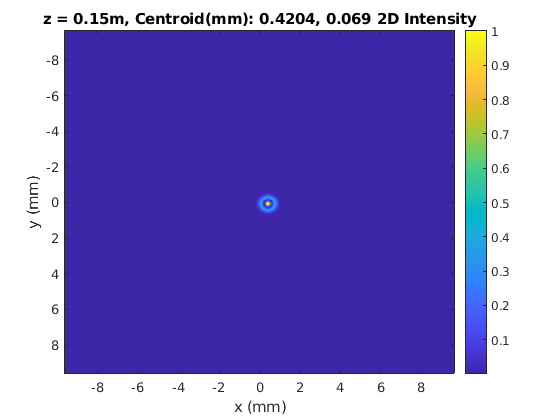

figure; % Create a new figure for the next plot

% Propagate the amplitude to 0.15 meters with the tilt phase applied
[propagated_coordinates, propagated_amplitude] = propagate_fresnel_2d(coordinates_centroid_example, complicated_amplitude .* tilt_phase, lambda, 0.15 * meter);

% Calculate centroid
[cx, cy] = centroid(propagated_coordinates, propagated_amplitude);
plot_2d_intensity(propagated_coordinates, propagated_amplitude, ['z = 0.15m, Centroid(mm): ', num2str(round(cx / millimeter, 4)), ', ', num2str(round(cy / millimeter, 4))]);

cx

cx = 4.2035e-04

cy

cy = 6.8983e-05

% Show all figures

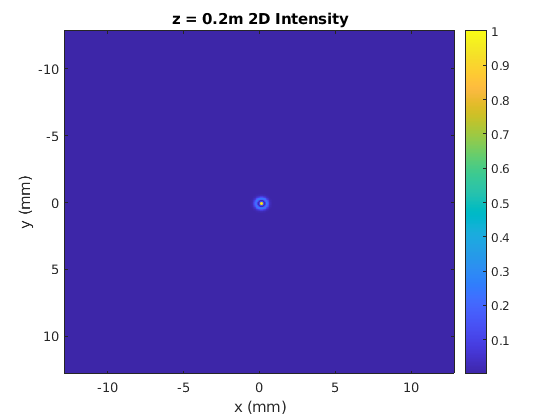

%%%TASK: 
%%%Propagate the example amplitude (complicated_amplitude) from z = 0 to z = 0.2m and z = 0.205m.
%%%Note we can essentially plot with the same coordinates for both z=0.2m and z = 0.205m, since the scale factor
%%%changes on the order of 2%
% Propagate the amplitude to 0.2 meters
[propagated_coordinates, propagated_amplitude] = propagate_fresnel_2d(%%%Fill in here);
plot_2d_intensity(propagated_coordinates, propagated_amplitude, 'z = 0.2m');

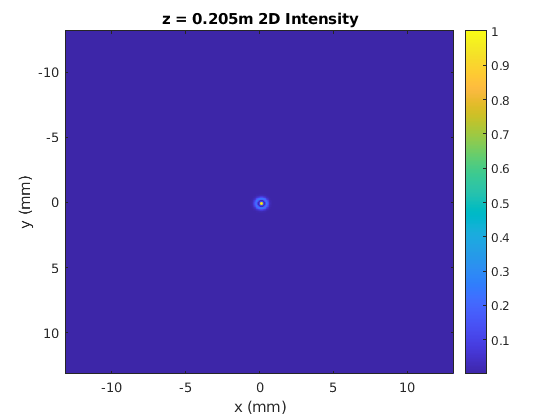

figure; % Create a new figure for the next plot

% Propagate the amplitude to 0.205 meters
[propagated_coordinates, propagated_amplitudep] = propagate_fresnel_2d(%%%Fill in here);
plot_2d_intensity(propagated_coordinates, propagated_amplitudep, 'z = 0.205m');

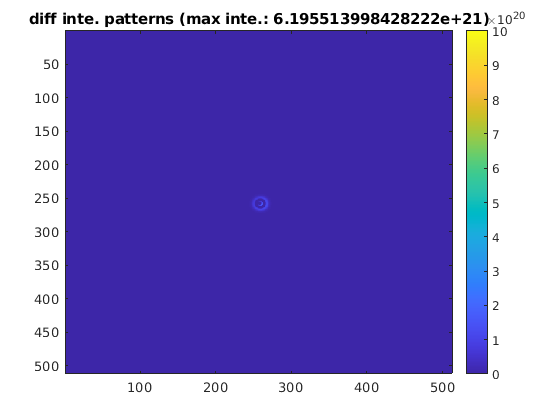

figure; % Create a new figure for the next plot

% Calculate the difference in intensity patterns
intensity_diff = abs(propagated_amplitude).^2 - abs(propagated_amplitudep).^2;

% Display the difference
imagesc(intensity_diff, [0 10^21]); % Set color limits for the display
colorbar; % Show color bar
title(['diff inte. patterns (max inte.: ', num2str(max((abs(propagated_amplitude).^2), [], 'all')), ')']);
saveas(gcf, 'diff_5mm_prop.png'); % Save the figure